# **PATCH ANTENNA DESIGN**

clear; clc; 

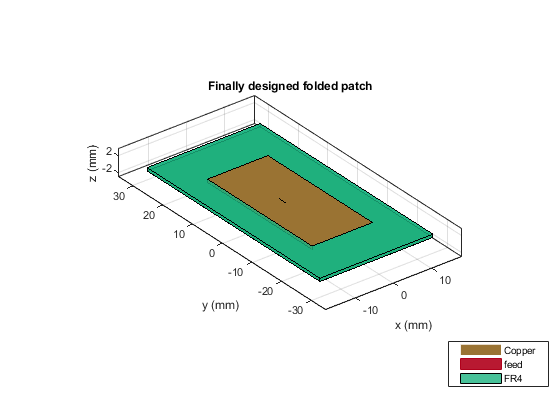

## BEAMWIDTH

## IMPEDANCE MATCHING

## IMPEDANCE DIAGRAM

## GAIN PATTERNS - dBi diagrams

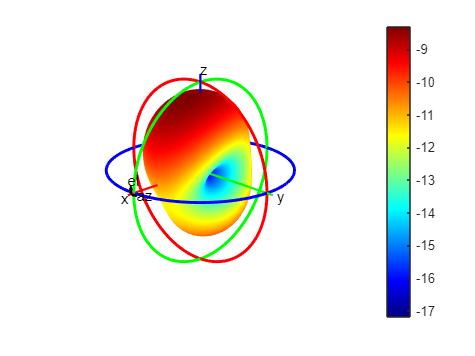

% diag structure is the same matricx as G0, except for subtracting
% - 2.15 dB to get from dBi scale to dB

[diag,AZ,EL] = pattern(p, f, 'Type', 'Gain');

ang1 = AZ';
ang2 = 90-(EL);
matr = diag';
th = linspace(0,360,37);
figure;
patternCustom(matr,ang2,ang1);

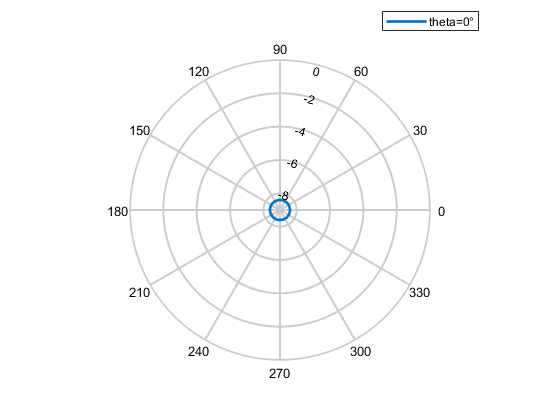

figure;
patternCustom(matr,ang2,ang1,'Slice','theta','SliceValue',0);

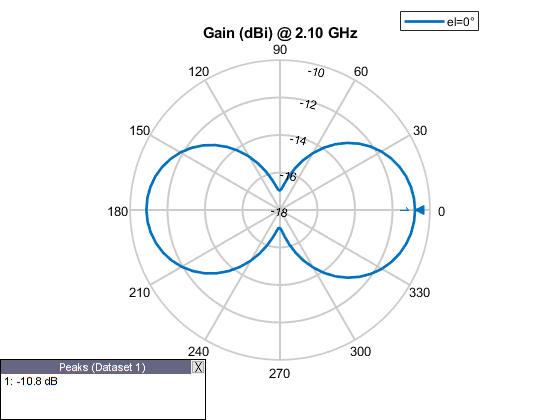

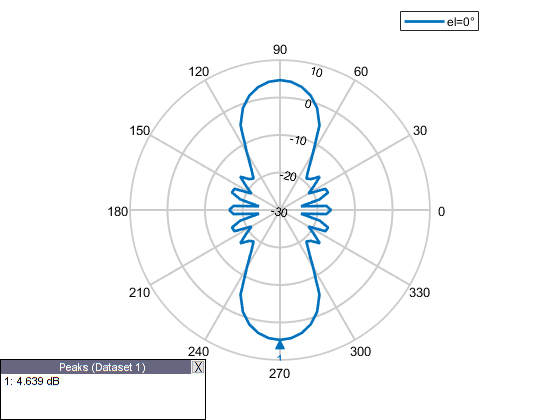

plotFrequency = 2.1e9;

pat_p = patternAzimuth(p, plotFrequency, 0, 'Azimuth', linspace(-180,180,73)); 
figure;
patternAzimuth(p, plotFrequency, 0, 'Azimuth', linspace(-180,180,73))

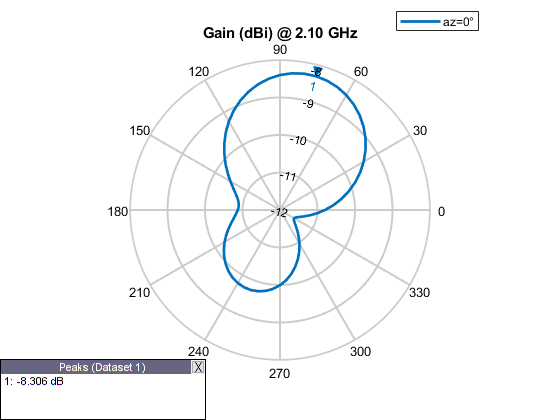

figure;
patternElevation(p, plotFrequency, 0, 'Elevation', 0:5:360)

## GAIN PATTERN - matrix in dB

% By running this, you get results in a different scale
% G0 = pattern(p, 2.1e9, 'Normalize',true,'Type', 'Gain');
G0 = pattern(p, 2.1e9,'Type', 'Gain');
G0 = G0+9;

newax = rotz(90);
pat_p = rotpat(G0,linspace(-180,180,73),linspace(-90,90,37),newax);
thet = linspace(-90,90,73);



figure;
patternCustom(pat_p, 90-theta, phi,'CoordinateSystem','polar',...
    'Slice','theta','SliceValue',0);

Error using patternCustom
The value of 'MagE' is invalid. Expected input to be of size 73x37, but it is of size 37x73.

Error in patternCustom (line 102)
parse(parseobj, MagE, theta, phi, varargin{:});

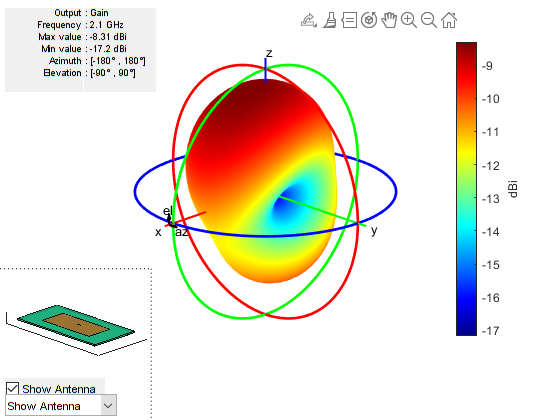


figure;
pattern(p, 2.1e9,'Type', 'Gain');

## GAIN PATTERNS - different polarization

% consider using vertical polarization for the matrix computation
pattern(p, f, 'Type', 'Gain', 'Polarization', 'v');
figure;
pattern(p, f, 'Type', 'Gain', 'Polarization', 'h');
figure;

## OTHER PLOTS

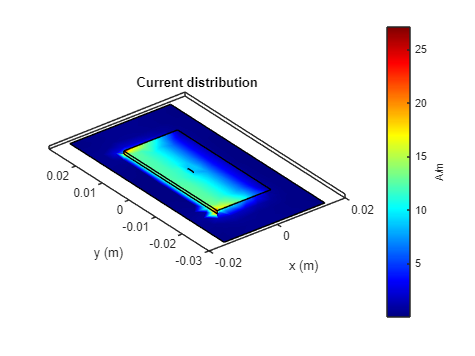

% CURRENT 
figure;
current(p, 2.1e9)

## DIRECTIVITY

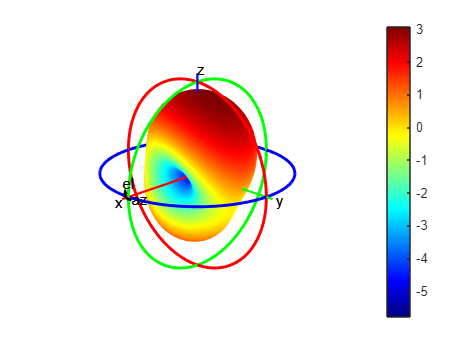


pat_dir = pattern(p,f,'Type','directivity');

az = linspace(-180,180,73);
el = linspace(-90,90,37);
newax = rotz(90);
pat2= rotpat(pat_dir,az,el,newax);

figure;
patternCustom(pat2',90-el,az);
% patternCustom(pat2',90-el,az);

## GAMMA PLOT

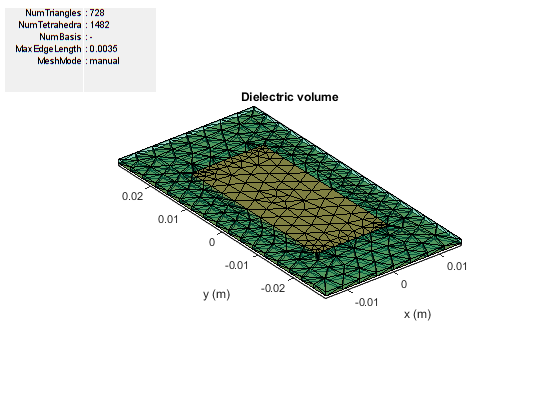

## FINDING OPTIMAL L,W by using contour plot

# **TCHEBYSHEV ARRAY**

tcheB = phased.ULA('NumElements',5,...
'ArrayAxis','x');
tcheB.ElementSpacing = 0.0939;
sll = 41.58;
chebn = chebwin(5, sll);
tcheB.Taper = chebn;

Cheb_Currents = 41.2*chebwin(5,sll);

% Assign Frequencies and Propagation Speed
%tcheB.Element = p;
tcheB.Element = antennaObject;

% short_dipole = phased.ShortDipoleAntennaElement; 
% figure;
% show(short_dipole);
% title('Phased short dipole');

% Array.Taper(1) = chebn(1);
% Array.Taper(2) = 0;
% Array.Taper(3) = 0;
% Array.Taper(4) = 0;
% Array.Taper(5) = 0;

Frequency = 2.1e9;
PropagationSpeed = 300000000;

% Assign Steering Angles
SteeringAngles = [0;90];
% Assign Phase shift quantization bits
PhaseShiftBits = 0;

% Create Figure

% Plot Array Geometry
figure;
viewArray(tcheB,'ShowNormal',false,...
  'ShowTaper',false,'ShowIndex','None',...
  'ShowLocalCoordinates',true,'ShowAnnotation',false,...
  'Orientation',[0;0;0]);

Error using sigutils.pvparse (line 29)
Input parameter ShowLocalCoordinates not recognized.
Error in phased.internal.AbstractArray/viewArray (line 708)
            sigutils.pvparse(varargin{:});

figure;
pattern(tcheB,2.1e9,'Normalize',false,'Type','directivity')

## FIRST PATTERN

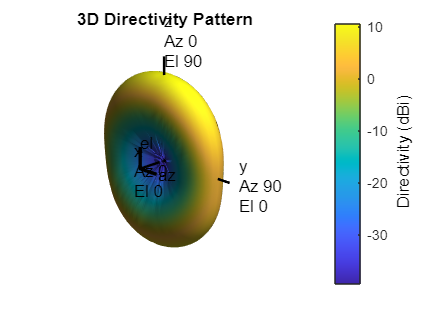

% Find the weights

Freq3D = 2.1e9; 

w = zeros(getNumElements(tcheB), length(Frequency));
SteerVector = phased.SteeringVector('SensorArray', tcheB,...
 'PropagationSpeed', PropagationSpeed, 'NumPhaseShifterBits', PhaseShiftBits(1));
for idx = 1:length(Frequency)
    w(:, idx) = step(SteerVector, Frequency(idx), SteeringAngles(:, idx));
end

% Plot 3d graph
format = 'polar';
figure;
pattern(tcheB, Freq3D , 'PropagationSpeed', PropagationSpeed,...
 'Type','directivity' , 'CoordinateSystem', format,'weights', w(:,1),...
  'ShowArray',false,'ShowLocalCoordinates',true,...
  'ShowColorbar',true,'Orientation',[0;0;0]);

Gt_patches = pattern(tcheB, Freq3D , 'PropagationSpeed', PropagationSpeed,...
 'Type','directivity', 'CoordinateSystem', format,'weights', w(:,1),...
  'ShowArray',false,'ShowLocalCoordinates',true,...
  'ShowColorbar',true,'Orientation',[0;0;0]);
Gt_dipoli = Gt_dipoli - 2.15; 

Unrecognized function or variable 'Gt_dipoli'.

## GAIN PATTERN

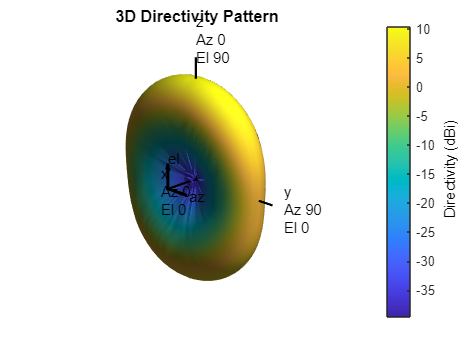

gain = phased.ArrayGain('SensorArray',tcheB);
% ang_phi = linspace(-180,180,360);
% ang_theta = linspace(-90,90,360);

ang_phi = linspace(-180,180,73);
ang_theta = linspace(-90,90,37);
g = zeros(length(ang_phi),length(ang_theta));
for i=1:73
    for j=1:37
g(i,j) = gain(2.1e9,[ang_phi(i);ang_theta(j)]);
% g = gain(fc,[30;20])
    end
end
g_pat = pattern(tcheB,2.1e9,ang_phi,ang_theta);
pattern(tcheB,2.1e9,ang_phi,ang_theta);

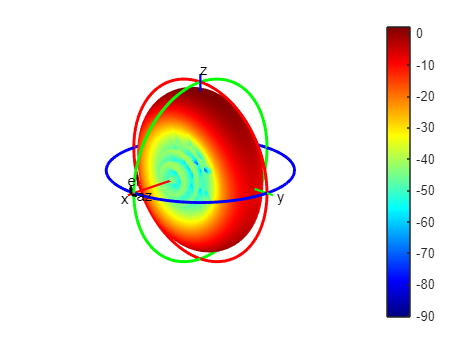

figure;
patternCustom(g,90-ang_theta,ang_phi);

figure;
g_pat = pattern(tcheB,2.1e9,ang_phi,ang_theta);
pattern(tcheB,2.1e9,ang_phi,ang_theta);

GGGF = abs(g).^2/(Cheb_Currents(3)^2+Cheb_Currents(2)^2+Cheb_Currents(3)^2);
Gpartial = g_pat./GGGF;

Arrays have incompatible sizes for this operation.

Related documentation

object_g = g_pat./g';

# **ARRAY FACTOR**

SubObject = design(helix, 2100*1e6);
arrayhelix = design(linearArray('Element', SubObject), 2100*1e6, SubObject);
arrayhelix.NumElements = 5;
arrayhelix.ElementSpacing = 0.0939;
% arrayhelix.AmplitudeTaper = [chebn(1), chebn(2), chebn(3), chebn(4), chebn(5)];


## PATTERN MULTIPLICATION PRINCIPLE

arrayhelix.AmplitudeTaper = [chebwin(1), chebwin(2), chebwin(3), chebwin(4), chebwin(5)];

Error using horzcat
Dimensions of arrays being concatenated are not consistent.


[PAT,AZ,EL] = arrayFactor(arrayhelix, 2.1e9);
phi = AZ';
theta = 90-(EL);
MagE = PAT';
th = linspace(0,360,37);
figure;
patternCustom(PAT',theta,phi);
figure; 
arrayFactor(arrayhelix, 2.1e9);
Factor = arrayFactor(arrayhelix, 2.1e9);
angoli = linspace(0,360,73);

Gf = (PAT.^2)/(2*Cheb_Currents(1)^2+2*Cheb_Currents(2)^2+Cheb_Currents(3));

% C0 = Cheb_Currents(3);
% C1 = Cheb_Currents(2);
% C2 = Cheb_Currents(1);
% Gf = (Factor.^2)/(2*C2^2+2*C1^2+C2^2);

 etaT = 0.79; 
% GTOT = etaT*dip_fact.*Factor;
figure;
patternCustom(Factor',theta,phi);

Unrecognized function or variable 'Factor'.

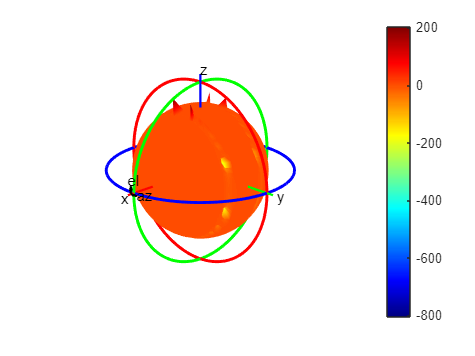

 etaT = 0.79;
 Gain_FACTOR = Gt_patches./(etaT*pat2); 
 Gain_ELEMENT = Gt_patches./(etaT*Factor.*Factor);
figure;
patternCustom(Gain_ELEMENT',90-el,az);


C_0 = Cheb_Currents(3);
C_1 = Cheb_Currents(2);
C_2 = Cheb_Currents(1);

% Array_Factor = abs(sqrt(Gain_FACTOR*(2*chebn(1)^2+2*chebn(2)^2+chebn(3)^2)));
% figure;
% patternCustom(Array_Factor',90-el,az);

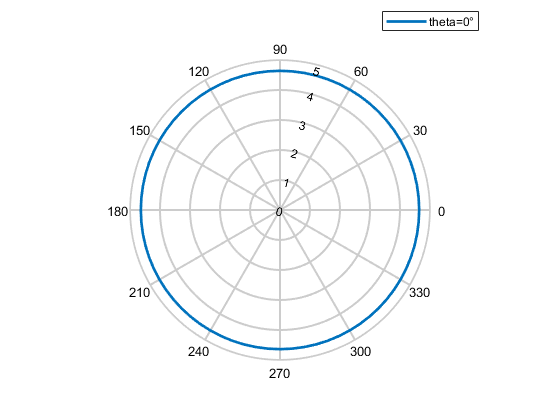

Factor_slice = patternCustom(Factor',theta,phi,'Slice','theta','SliceValue',0);

figure;
patternCustom(Factor',theta,phi,'Slice','theta','SliceValue',0);

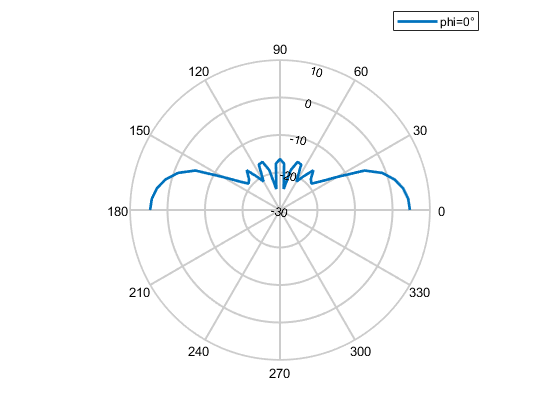

figure;
patternCustom(Factor',theta,phi,'Slice','phi','SliceValue',0);

## Array factor computed by equations

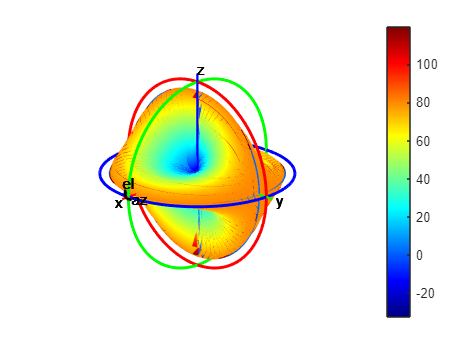

C0 = 41.2;
C1 = 29.7245;
C2 = 9.6243;

d = 0.0939;
lambda0 = 0.142;
theta = linspace(-90,90,37);
phi = linspace(-180,180,73); 

d = 0.0939; 
u = zeros(73,37);
for i=1:73
    for j=1:37
u(i,j) = (pi*d/lambda0)*cos(deg2rad(phi(i)))*sin(deg2rad(theta(j)));
% g = gain(fc,[30;20])
    end
end

ArF = zeros(73,37);
for i=1:73
    for j=1:37
ArF(i,j) = C0*cos(u(i,j))+C1*cos(3*u(i,j))+C2*cos(5*u(i,j));
    end
end
Gain_factor = ArF.^2/(C0^2+2*C1^2+2*C2^2);
patternCustom(ArF,90-theta,phi);

## NEAR FIELD 

L_max = 5*W+4*0.0939; 
LL = linspace(0,L_max,1);
[X,Y]=meshgrid(LL,LL); 
fre=0.68*sqrt((L_max)^3/lambda0);
pfre=[X(:)';Y(:)';(fre/2)*ones(1,prod(size(X)))];




figure;
EHfields(tcheB,f,[1; 1; 1])

Check for incorrect argument data type or missing argument in call to function 'EHfields'.